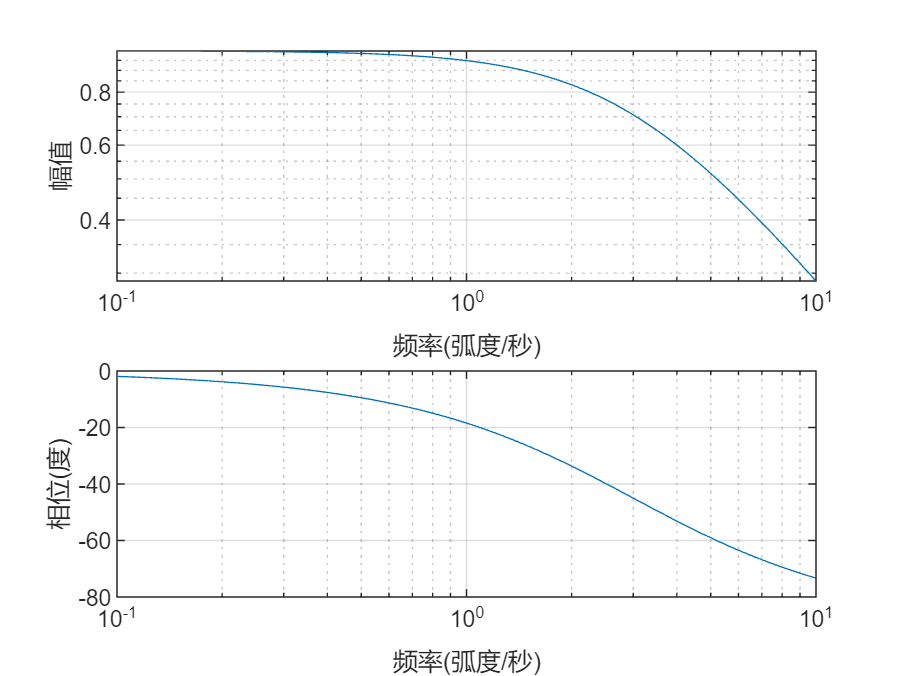

a=[1 3];
b=3;
freqs(b,a);

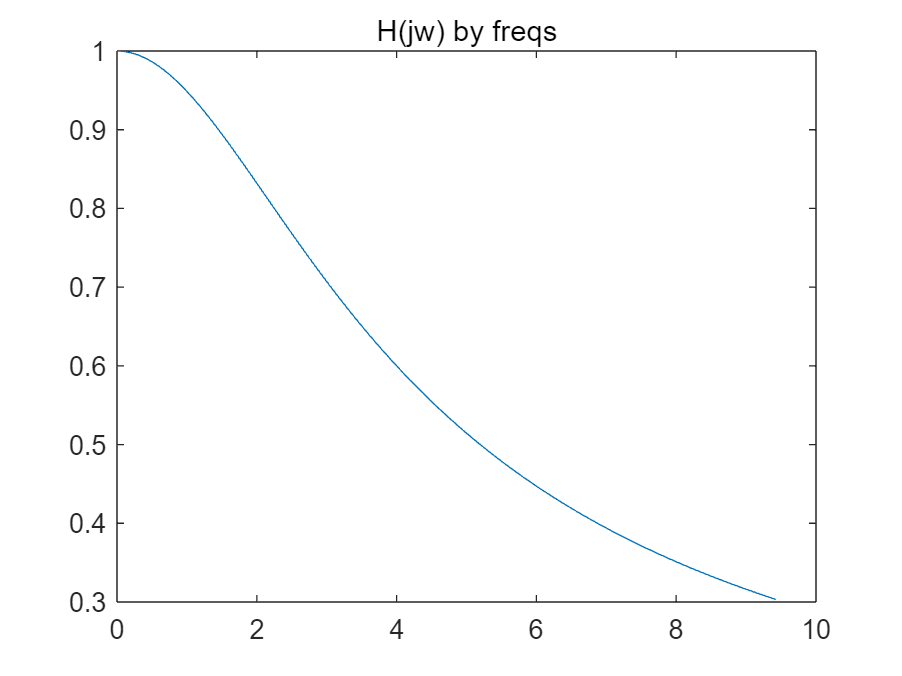

w=linspace(0,3*pi);
H=freqs(b,a,w);
figure;
plot(w,abs(H));
title('H(jw) by freqs');

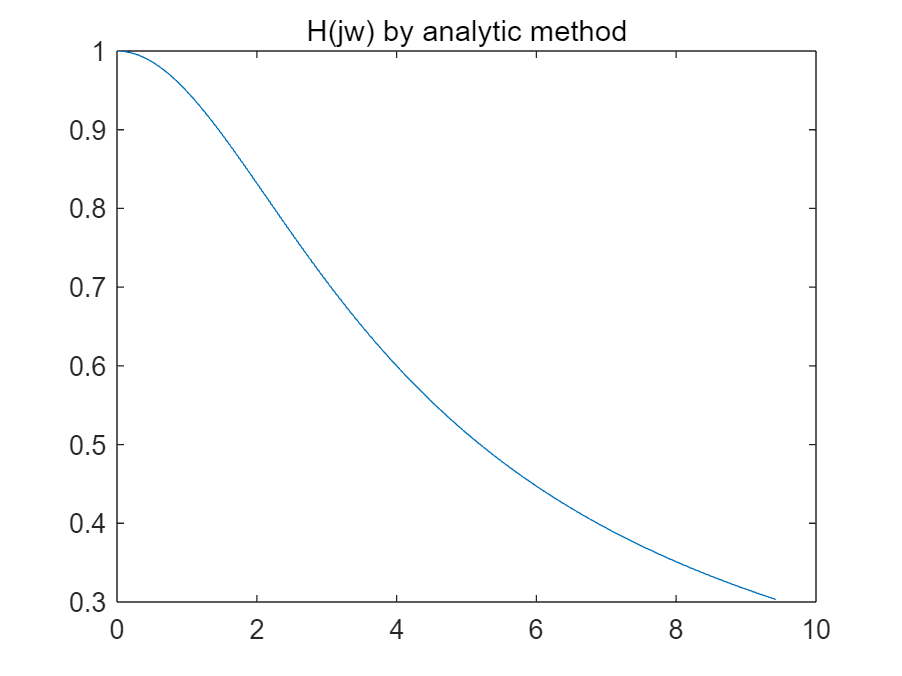

figure;
plot(w,abs(3./(3+1j*w)));
title('H(jw) by analytic method');%微分方程解析直接算

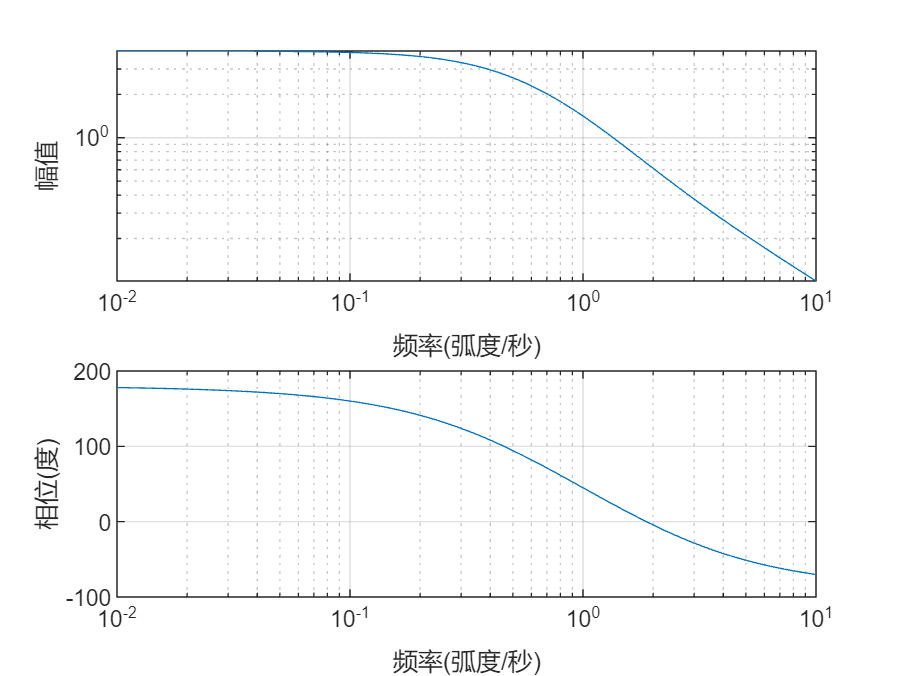

clc,clear,close all;
a=[1 1.5 0.5];
b=[1 -2];
freqs(b,a);

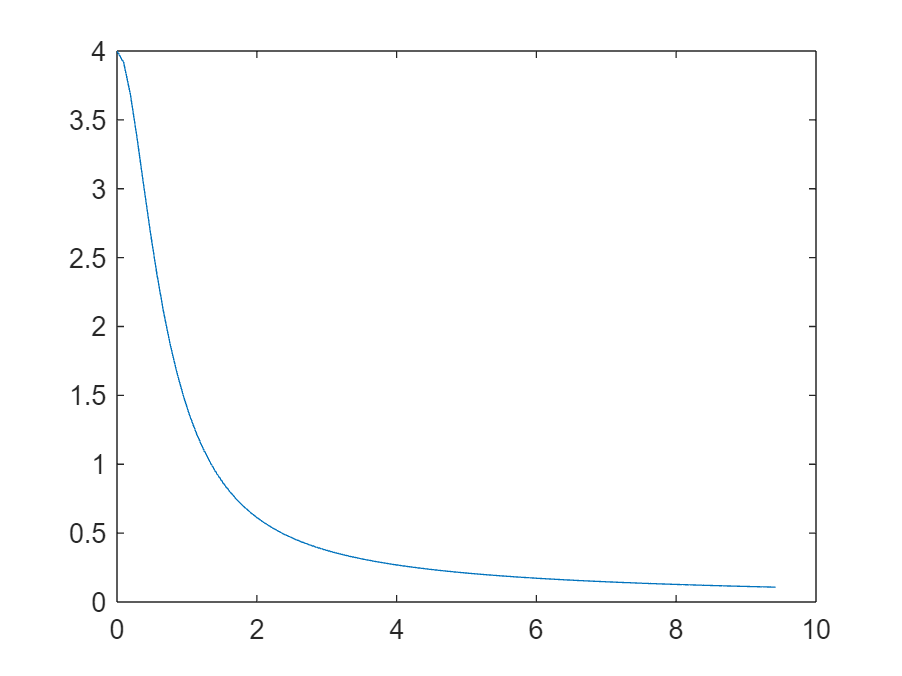

w=linspace(0,3*pi);
figure;
plot(w,abs((1i*w-2)./((1i*w).^2+1.5*1i*w+0.5)));

clc,clear,close all;
b=[3 10 5];
a=[1 7 16 12];
[r,p,k]=residue(b,a);
r

r =     2.0000
    1.0000
   -3.0000


p

p =    -3.0000
   -2.0000
   -2.0000


k


k =

     []



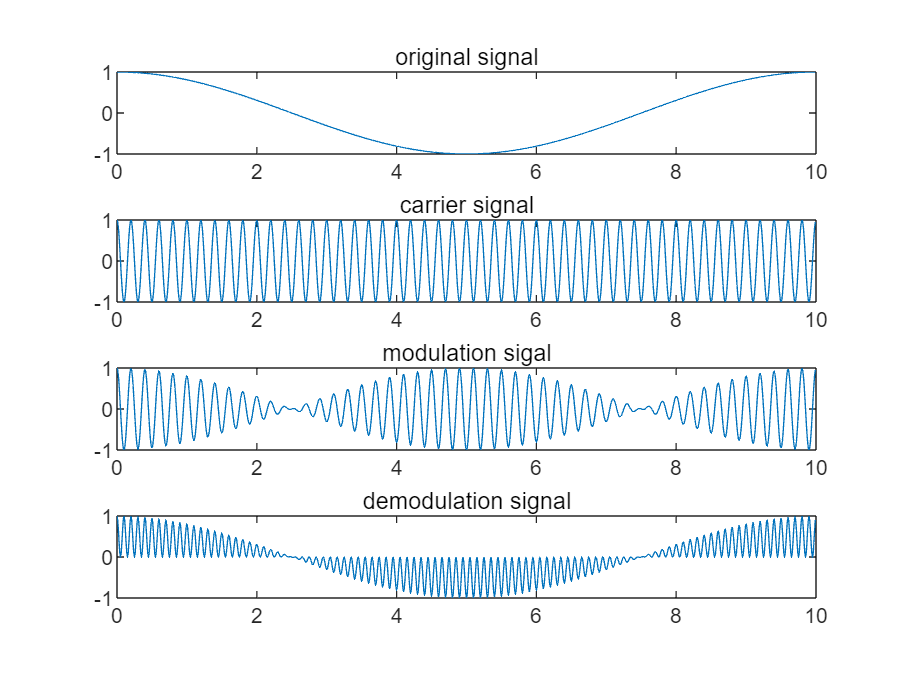

clc,clear,close all;
figure;
t=0:0.01:10-0.01;
x=cos(2*pi*0.1*t);
subplot(4,1,1),plot(t,x),title('original signal');
m=cos(2*pi*5*t);
subplot(4,1,2),plot(t,m),title('carrier signal');
y=x.*m;
subplot(4,1,3),plot(t,y),title('modulation sigal');
z=y.*m;
subplot(4,1,4),plot(t,z),title('demodulation signal');

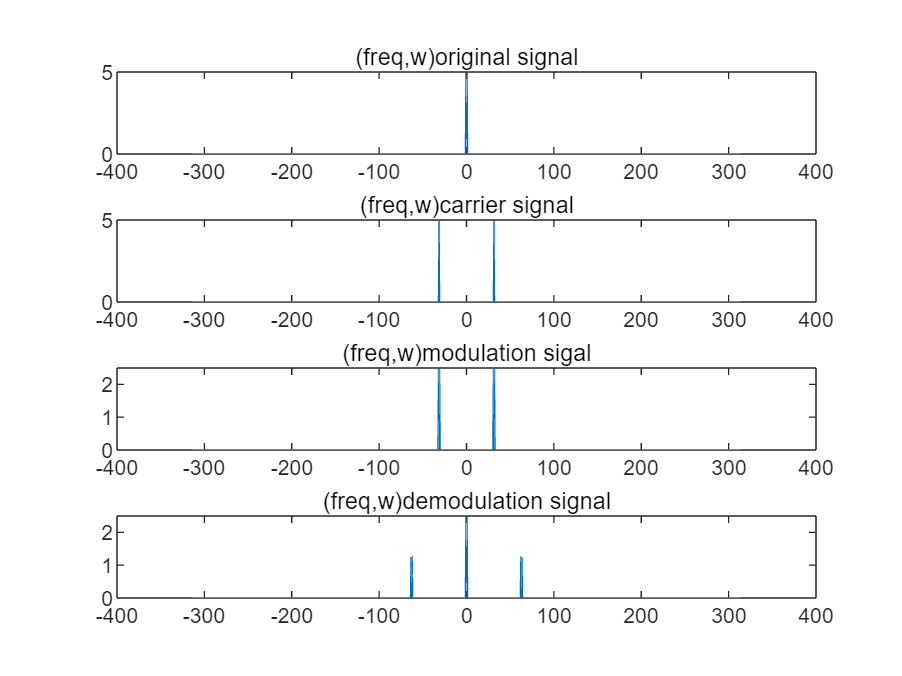

figure;
tau=0.01;
N=length(t);
nw=0:2*pi/N/tau:(N-1)*2*pi/N/tau;
w=-pi/tau+nw;
f=w/2/pi;
X=abs(fftshift(tau*fft(x)));
subplot(4,1,1),plot(w,X),title('(freq,w)original signal');
M=abs(fftshift(tau*fft(m)));
subplot(4,1,2),plot(w,M),title('(freq,w)carrier signal');
Y=abs(fftshift(tau*fft(y)));
subplot(4,1,3),plot(w,Y),title('(freq,w)modulation sigal');
Z=abs(fftshift(tau*fft(z)));
subplot(4,1,4),plot(w,Z),title('(freq,w)demodulation signal');

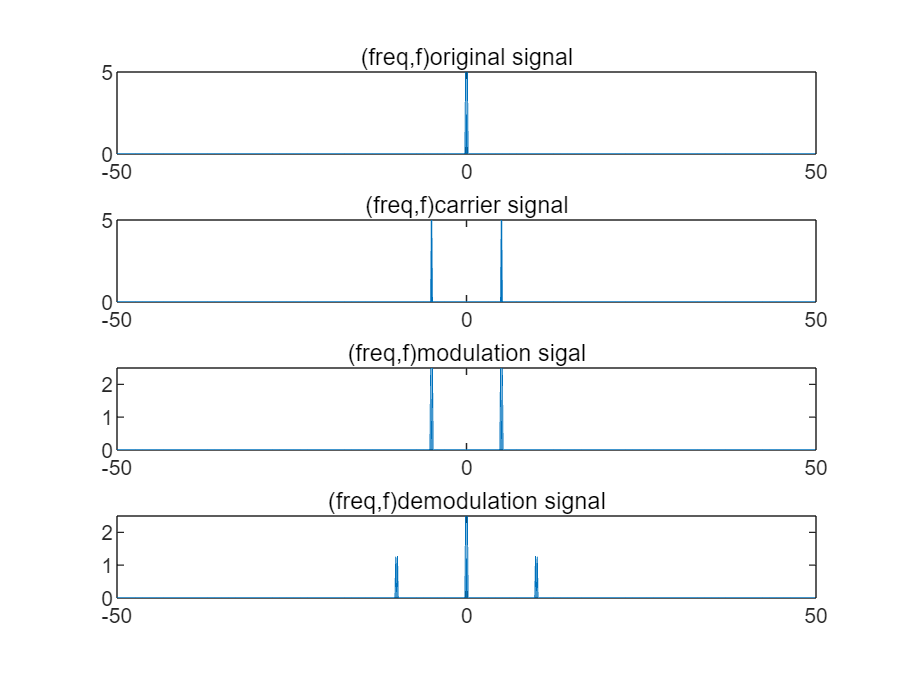

figure;
subplot(4,1,1),plot(f,X),title('(freq,f)original signal');
subplot(4,1,2),plot(f,M),title('(freq,f)carrier signal');
subplot(4,1,3),plot(f,Y),title('(freq,f)modulation sigal');
subplot(4,1,4),plot(f,Z),title('(freq,f)demodulation signal');